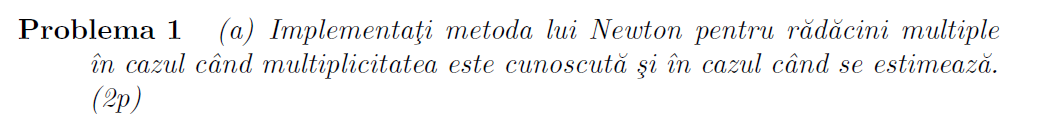

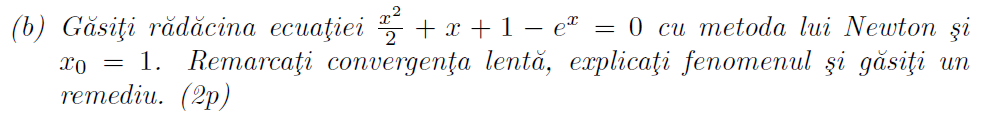

syms x
f = @(x) (x^2) / 2 + x + 1 - exp(x);
fd = @(x) x + 1 - exp(x);

x0 = 1;
[rad, iter] = NewtonNecunoscuta(f, fd, x0, 1e-6)

rad = 3.8608e-06

iter = 10

valoare_functie = f(rad)

valoare_functie = 0

Convergenta este lenta, 

clear
syms x
f = @(x) x^2 - 4;
fd = @(x) 2*x;
x0 = 100;
%{
tic;
multiplicitate = 3;
fprintf("Metoda newton cu multiplicitate cunoscuta:")
[rezultat, iter] = NewtonCunoscuta(f, fd, x0, multiplicitate, 1e-5)
timp_executie1 = toc;
disp(['Timpul de execuție: ', num2str(timp_executie1), ' secunde.']);

tic;
fprintf("Metoda newton cu multiplicitate necunoscuta:")
[rezultat, iter] = NewtonNecunoscuta(f, fd, x0, 1e-5)
timp_executie2 = toc;
disp(['Timpul de execuție: ', num2str(timp_executie2), ' secunde.']);

timp_executie2 - timp_executie1
%}

Metoda cand nu se cunoaste multiplicitatea o consider mai inceata, pentru ca este costisitor sa calculam de fiecare data numarul de multiplicitate.